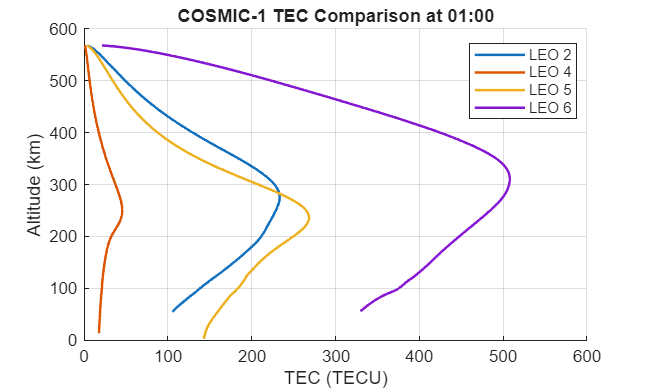

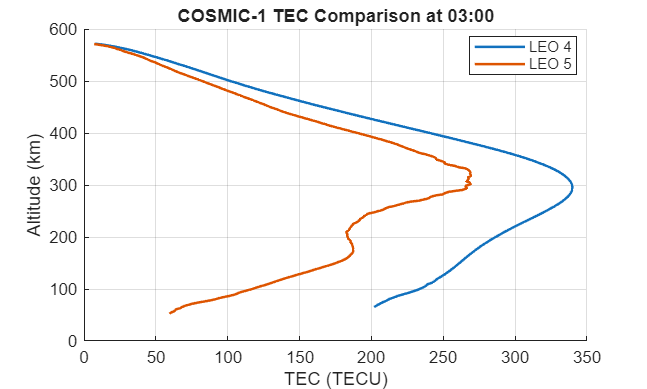

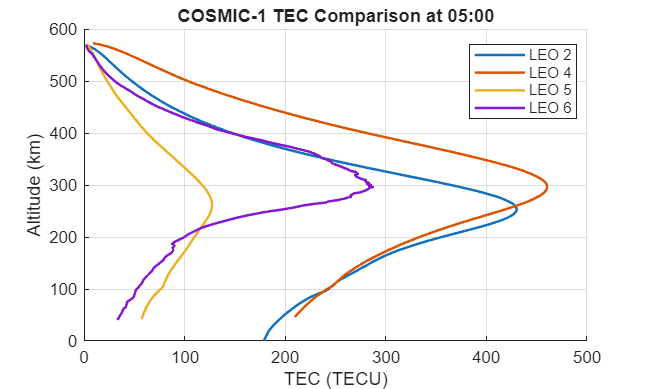

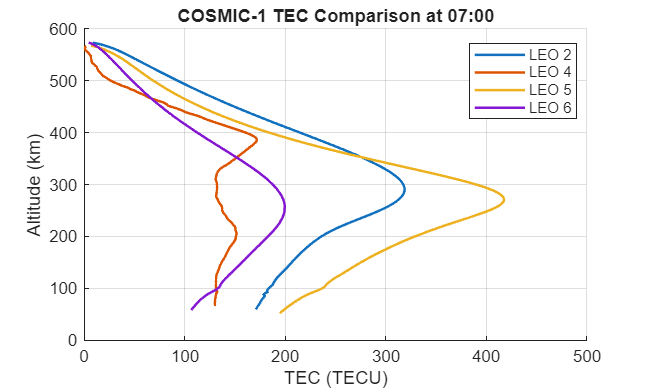

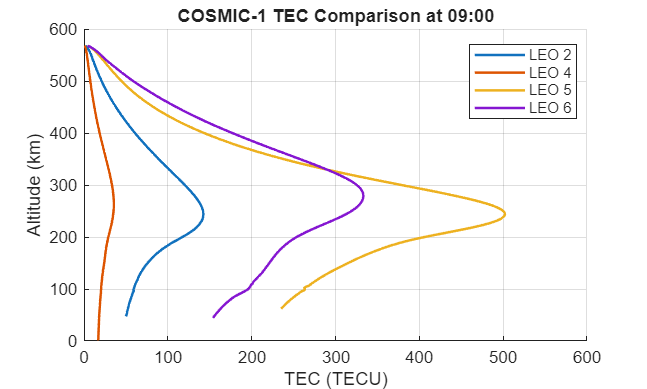

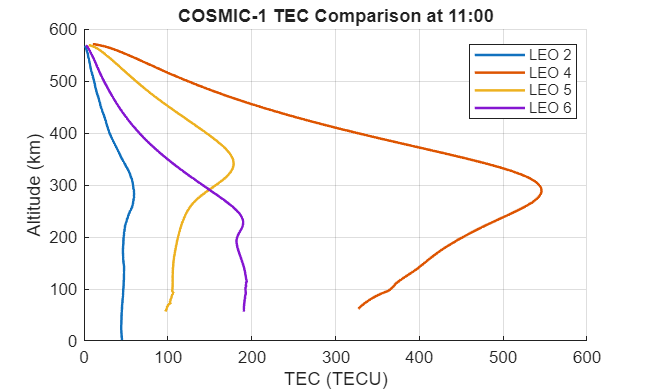

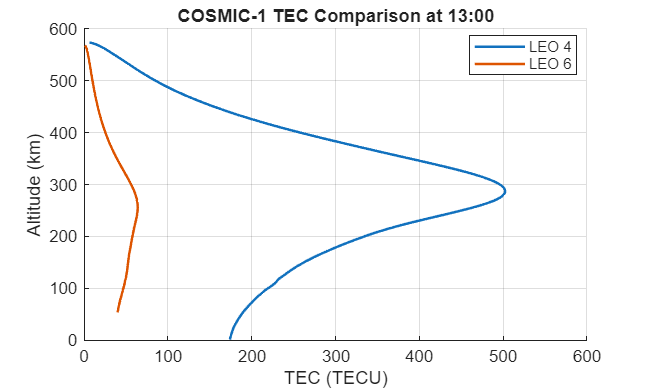

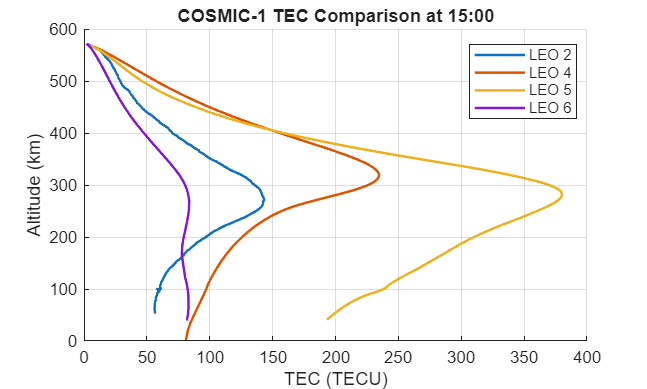

% Compare TEC of all LEOs at a specific moment
for target_hour = 1:2:23
time_tolerance = 60;
target_minute = 00;
target_alt = 400;
minHour = target_hour-(time_tolerance/60);
maxHour = target_hour+(time_tolerance/60);
figure
    hold on

    legend_entries = strings(6,1);

    for leo = 1:6

        match_idx = [];

        for i = 1:length(COSMIC_data)

            if COSMIC_data{i}.LEO_ID == leo && ...
               COSMIC_data{i}.hour == target_hour && ...
               abs(COSMIC_data{i}.minute - target_minute) <= 10

                match_idx = i;
                break
            end
        end

        if ~isempty(match_idx)

            TEC = COSMIC_data{match_idx}.TEC_cal;
            ALT = COSMIC_data{match_idx}.MSL_alt;

            plot(TEC, ALT, 'LineWidth', 1.5)

            legend_entries(leo) = "LEO " + leo;

        end
    end

    xlabel('TEC (TECU)')
    ylabel('Altitude (km)')
    title(['COSMIC-1 TEC Comparison at ', ...
           num2str(target_hour,'%02d'), ':', ...
           num2str(target_minute,'%02d')])

    legend(legend_entries(legend_entries ~= ""), 'Location','best')
    grid on
    hold off

%{
figure
hold on

target_time = target_hour*60 + target_minute;
time_tolerance = 60;
colors = lines(6);  % distinct colours for each LEO


for leo = 1:6

    peak_TEC = [];
    peak_lon = [];

    for i = 1:length(COSMIC_data)

        if COSMIC_data{i}.LEO_ID ~= leo
            continue
        end

        % ---- Time filter ----
        file_time = COSMIC_data{i}.hour*60 + COSMIC_data{i}.minute;

        if abs(file_time - target_time) > time_tolerance
            continue
        end

        % ---- Extract data ----
        TEC = COSMIC_data{i}.TEC_cal;
        LON = COSMIC_data{i}.GEO_lon;

        valid = ~isnan(TEC) & ~isnan(LON);
        TEC = TEC(valid);
        LON = LON(valid);

        if isempty(TEC)
            continue
        end

        % ---- Find peak ----
        [maxTEC, idx_max] = max(TEC);

        peak_TEC(end+1,1) = maxTEC;
        peak_lon(end+1,1) = LON(idx_max);

    end

    % ---- Plot for this satellite ----
    % Add this check BEFORE sorting/interpolating
    if isempty(peak_lon) || length(peak_lon) < 2
        fprintf('LEO %d: insufficient data points, skipping.\n', leo);
        continue
    end
    
    % Sort data
    [peak_lon_sorted, sort_idx] = sort(peak_lon);
    peak_TEC_sorted = peak_TEC(sort_idx);
    
    % Remove duplicate longitudes
    [peak_lon_sorted, unique_idx] = unique(peak_lon_sorted);
    peak_TEC_sorted = peak_TEC_sorted(unique_idx);
    
    % Guard again after deduplication
    if length(peak_lon_sorted) < 2
        fprintf('LEO %d: insufficient unique longitudes after dedup, skipping.\n', leo);
        continue
    end
    
    % Create regular longitude grid
    lon_grid = -180:2:180;
    
    % Interpolation requires the query points to be within the data range
    % Clip lon_grid to data range to avoid NaN-only output
    lon_grid = lon_grid(lon_grid >= peak_lon_sorted(1) & lon_grid <= peak_lon_sorted(end));
    
    if isempty(lon_grid)
        fprintf('LEO %d: lon_grid out of data range, skipping.\n', leo);
        continue
    end
    
    % Interpolate
    TEC_interp = interp1(peak_lon_sorted, peak_TEC_sorted, lon_grid, 'pchip', NaN);
    
    % Smooth
    TEC_interp = smoothdata(TEC_interp, 'movmean', 5);
    
    % Plot
    plot(lon_grid, TEC_interp, ...
        'LineWidth', 1, ...
        'Color', colors(leo,:), ...
        'DisplayName', sprintf('LEO %d', leo));
end
xlabel('Longitude (deg)')
ylabel('Peak TEC (TECU)')
title(sprintf('Peak TEC vs Longitude near %02d:%02d ± %d min', ...
          target_hour, target_minute, time_tolerance))

legend('Location','best')
grid on
hold off
%}
end